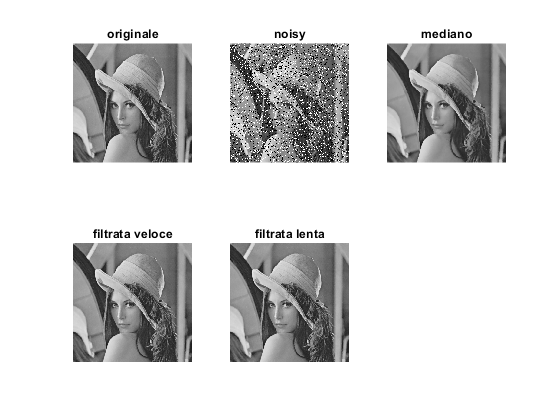

clc; close all; clear all;
x = imread('lena.jpg');

% Aggiunta rumore sale e pepe
n = imnoise(x,'salt & pepper',0.2);
n = double(n);

% Filtro mediano
y0 = medfilt2(n,[5 5],'symmetric');

% Filtraggio 1
M = colfilt(n,[5 5],'sliding',@max);
m = colfilt(n,[5 5],'sliding',@min);
med = colfilt(n,[5 5],'sliding',@median);
mask = double((n == M) | (n == m)); 
y1 = med.*mask + n.*(1-mask);

% Filtraggio 2
fun = @(x) custom_median(x);
y2 = nlfilter(n,[5 5],fun);

figure;
subplot(231); imshow(x,[0 255]); title('originale');
subplot(232); imshow(n,[0 255]); title('noisy');
subplot(233); imshow(y0,[0 255]); title('mediano');
subplot(234); imshow(y1,[0 255]); title('filtrata veloce');
subplot(235); imshow(y2,[0 255]); title('filtrata lenta');

function y = custom_median(x)
    m = min(x(:));
    M = max(x(:));
    if x(3,3) == m | x(3,3) == M,
        y = median(x(:));
    else
        y = x(3,3);
    end
end